% [S,Fs] = audioread('Music library\5 second a new beginning - Copy.mp3');
[S,Fs] = audioread('Music library\Cut down 30s\a new beginning cut.mp3');
S = mean(S,2);  
% plot(S)
% plot(abs(fft(S)))
N = length(S) % sample lenth

N = 1324272

slength = N/Fs

slength = 30.0288

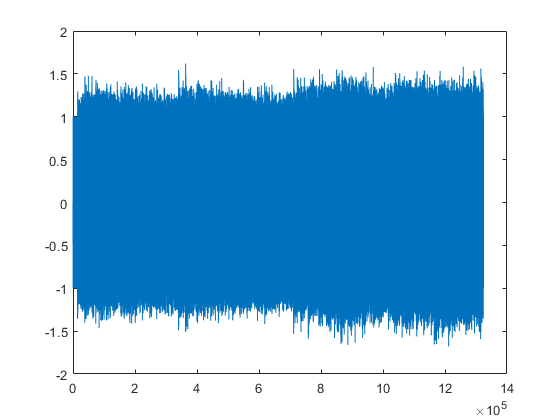


% len = slength;                                       % Length (sec)
f   = 1E+3;                                     % Frequency (Hz)
% Fs  = 8192;                                     % Sampling Frequency (Hz)
t   = linspace(0, slength, (Fs*slength) );                 % Time Vector

signal = sin(2*pi*f*t);
signal = signal';
test = S + signal;

plot(test)

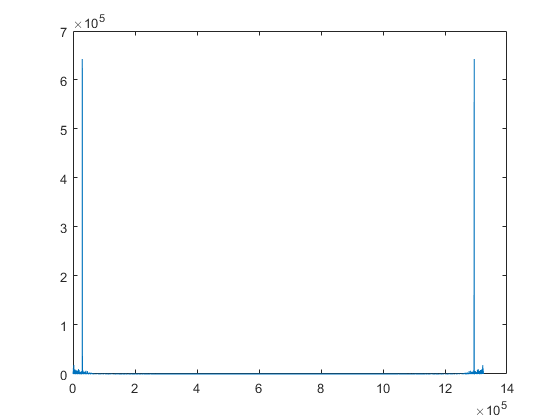

% hold on
plot(abs(fft(test)))
% plot(abs(fft(S)))
 thing3 = bandstop(test,[950 1050],Fs);

hplayer = audioplayer(thing3, Fs);
play(hplayer);
pause(5);

% [A,B,C,D] = butter(20,[5000 5200]/(Fs/2),"stop");

% d = designfilt('bandstopiir','FilterOrder',20, ...
%     'HalfPowerFrequency1',29550,'HalfPowerFrequency2',30500, ...
%     'SampleRate',Fs);

% [b,a] = butter(5,[2.955e4 3.05e4]/(Fs/2),'stop');


% [d,c] = cheby1(5,5,[5000 5200]/(Fs/2),'stop');
% fvtool(d,c)
% tic
thing = filter(b,a,test);
% toc
% poop = toc
% tic
thing2 = filter(d,c,test);
% Rtoc
% poop2 = toc
% plot(S)
hold off

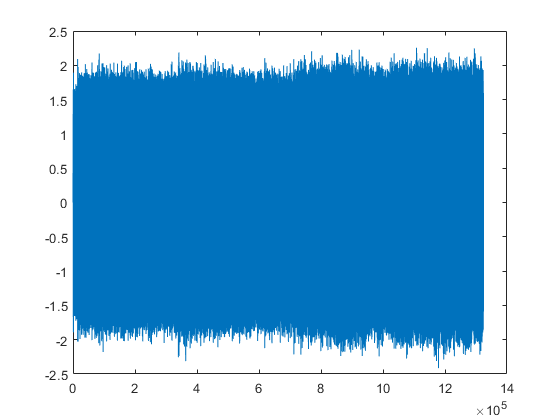

plot(thing)

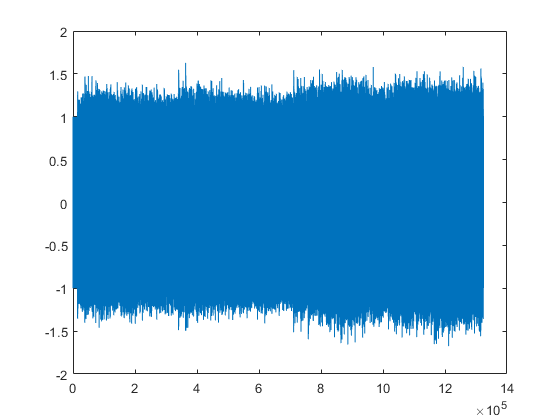

plot(thing2)

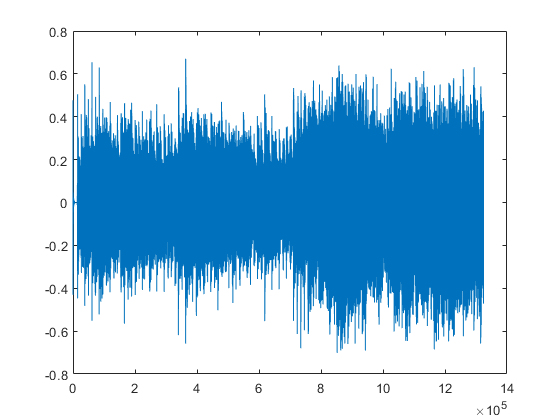




 
 plot(thing3)

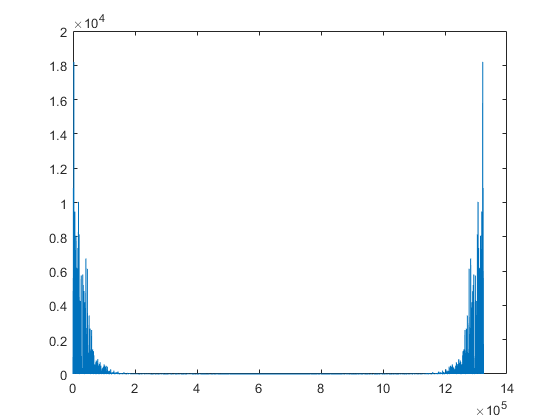

plot(abs(fft(thing3)))

x= 5;

CustomCompare(thing,thing2)

% 
% test = mean(abs(thing-thing2)) % mean(abs(A-B))
% 
CustomCompare(thing, S)
CustomCompare(thing2, S )
% fvtool(d)

%         [C,lag] = xcorr(thing2,S);
% 
%         [~,I] = max(abs(C));
%         SampleDiff = lag(I);
%         
% %         delay = finddelay(secondNumbers,firstNumbers); %not needed as SampleDiff does this
%         
%         if (SampleDiff + numel(thing2)) > numel(S)+ fs %|| SampleDiff<0
%             Result = "Probably not the same";      %TODO: Should make Result function
%             similarityCoefficient = Result;
%         elseif ( SampleDiff == 0)
%             cc = corrcoef(thing2,S);
%             similarityCoefficient = cc(1,2);
%         else
%             closestMatched = S(SampleDiff:numel(thing2) + SampleDiff -1);
%             cc = corrcoef(thing2,closestMatched);
%             similarityCoefficient = cc(1,2);
%         end 
% 







% thing = filtfilt(d,S);

% sos = ss2sos(A,B,C,D);
% fvt = fvtool(sos,d,'Fs',Fs);

% legend(fvt,'butter','designfilt')
% plot(abs(fft(thing)))

% hplayer = audioplayer(thing, Fs);
% play(hplayer);
% hold on
% plot(abs(fft(thing)))
% plot(abs(fft(S)))



% 
% newWave = awgn(S,20,'measured');
% 
% 
% len = 5;                                       % Length (sec)
% f   = 1E+5;                                     % Frequency (Hz)
% Fs  = 8192;                                     % Sampling Frequency (Hz)
% t   = linspace(0, len, Fs*len);                 % Time Vector
% 
% signal = sin(2*pi*f*t);                         % Signal (10 kHz sine)
% 
% % sound(signal, Fs)                               % Original Signal
% % 
% noise = signal + 0.1*randn(size(signal));
% noise = noise';
% % pause(len+0.5)                                       % Wait For First Sound To Finish Playing
% % sound(noise, Fs)                                % Noisy Signal
% % pause(len+0.5)
% 
% % Remove white noise
% % Design a lowpass filter with passband frequency of 1 kHz, and stopband
% % frequency of 1.4 kHz. Choose a minimum order design.
% Fp = 1e3;    % Passband frequency in Hz
% Fst = 1.4e3; % Stopband frequency in Hz
% Ap = 1;      % Passband ripple in dB
% Ast = 95;    % Stopband attenuation in dB
% 
% % Design the filter 
% df = designfilt('lowpassfir','PassbandFrequency',Fp,...
%                 'StopbandFrequency',Fst,'PassbandRipple',Ap,...
%                 'StopbandAttenuation',Ast,'SampleRate',Fs);
%             
% % fd = design(df,"equiripple");
% % plot(fd)
%  % Filter the data and compensate for delay
% D = mean(grpdelay(df)); % filter delay
% ylp = filter(df,[noise; zeros(D,1)]);
% zeros(D,1);
% ylp = ylp(D+1:end);   
% sound(ylp,Fs)
% pause(len+0.5)
% yf = filtfilt(df,ylp);
% sound(yf,Fs)
% 
% 
% 
% 
% % hold on
% plot(abs(fft(signal)))
% plot(abs(fft(noise)))
% plot(abs(fft(ylp)))
% % plot(noise)
% % plot(signal)
% % plot(ylp)
% % hold off
% 
% 
% 
% % len = 5;                                       % Length (sec)
% % fff   = 1E+4;                                     % Frequency (Hz)
% %                                 % Sampling Frequency (Hz)
% % t   = linspace(0, len, Fs*len);                 % Time Vector
% % signal = sin(2*pi*fff*t);                         % Signal (10 kHz sine)
% %                          % Original Signal
% % noise = S + 0.1*randn(size(signal));
% % 
% % 
% % plot(noise)
% % plotfft(noise)
% 
% 
% 
% 
% 
% 
% 
% 
%         
% 
% 
% 
% 
% 
% % hplayer = audioplayer(ylp, Fs);
% % play(hplayer);
% 
% 
% 
% 
% 
% % fart1 = fft(S);
% % fart2 = fft(newWave);
% 
% % hold on
% % plot(newWave)
% % plot(S)
% % hold off
% 
% 
% % plot(abs(fart2))
% % plot(abs(fart1))
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
